# 测试（间接法）

clc
clear
close all
addpath("src\");

## 太阳帆轨道转移

r      = 1; % AU
theta  = 0;
vr     = 0;
vtheta = 1;
x1 = [r theta vr vtheta];
x2 = [1.524 0 0 1 / sqrt(1.524)];

t_max = 10;

p.beta  = -0.16892;
p.tspan = 0.01;

### 无推力

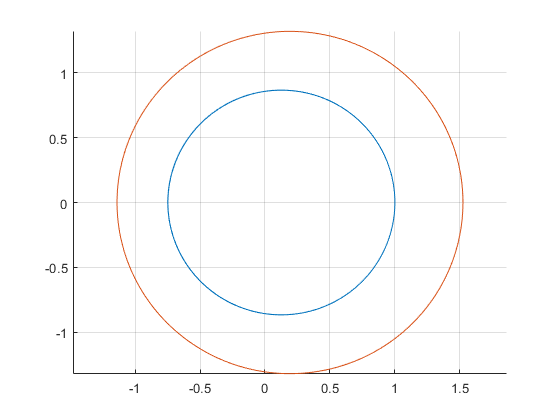

[~, s1] = ode45(@(t, x) SolarSailEq(t, x, 0, p), 0 : p.tspan : t_max, x1);
[~, s2] = ode45(@(t, x) SolarSailEq(t, x, 0, p), 0 : p.tspan : t_max, x2);
figure
hold on
plot(s1(:, 1) .* cos(s1(:, 2)), s1(:, 1) .* sin(s1(:, 2)))
plot(s2(:, 1) .* cos(s2(:, 2)), s2(:, 1) .* sin(s2(:, 2)))
grid on
axis equal

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    9.000000e+00    1.003e+00    9.524e-01
    1      12    8.046512e+00    7.056e-01    9.524e-01    1.055e+00
    2      21    8.413852e+00    7.666e-02    9.524e-01    1.228e+00
    3      34    8.246465e+00    8.880e-02    9.227e-01    2.992e-01
    4      45    8.078495e+00    9.664e-02    9.137e-01    2.996e-01
    5      52    7.905396e+00    1.025e-01    9.090e-01    2.991e-01
    6      73    7.905231e+00    1.031e-01    9.012e-01    2.927e-04
    7      80    7.904844e+00    1.031e-01    9.012e-01    5.774e-04
    8      94    7.904803e+00    1.027e-01    9.012e-01    7.318e-05
    9     101    7.904747e+00    1.027e-01    9.012e-01    7.083e-05
   10     113    7.904726e+00    1.029e-01    9.012e-01    3.659e-05
   11     120    7.904672e+00    1.029e-01    9.012e-01    7.120e-05
   12     132    7.904651e+00    1.028e-01    9

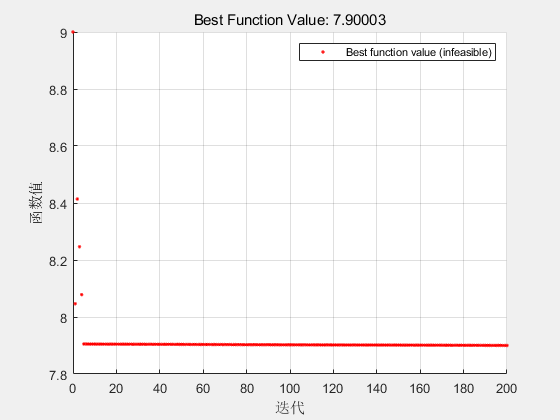


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.



[s,fval,exitflag,output] = IndirOptTimeSs(@(t, x) SolarSailTimeOpt(t, x, p), x1, x2, t_max, p);

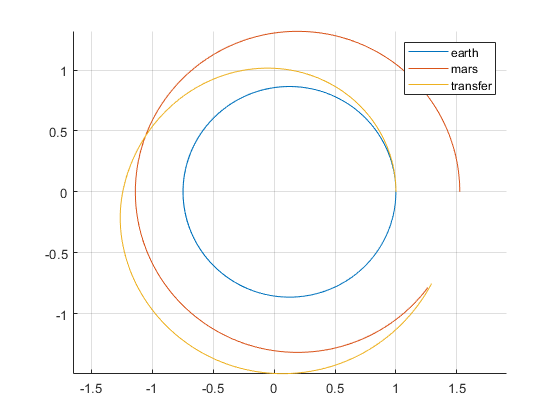

t = s(:, 1);
s(:, 1) = [];
[~, s1] = ode45(@(t, x) SolarSailEq(t, x, 0, p), 0 : p.tspan : t(end), x1);
[~, s2] = ode45(@(t, x) SolarSailEq(t, x, 0, p), 0 : p.tspan : t(end), x2);
figure
hold on
plot(s1(:, 1) .* cos(s1(:, 2)), s1(:, 1) .* sin(s1(:, 2)))
plot(s2(:, 1) .* cos(s2(:, 2)), s2(:, 1) .* sin(s2(:, 2)))
plot(s(:, 1) .* cos(s(:, 2)), s(:, 1) .* sin(s(:, 2)))
legend('earth', 'mars', 'transfer')
grid on
axis equal

[s] = IndirOptTimeSs2(@(t, x) SolarSailTimeOpt(t, x, p), x1, x2, [t s], p);
t = s(:, 1);
s(:, 1) = [];
[~, s1] = ode45(@(t, x) SolarSailEq(t, x, 0, p), 0 : p.tspan : t(end), x1);
[~, s2] = ode45(@(t, x) SolarSailEq(t, x, 0, p), 0 : p.tspan : t(end), x2);
figure
hold on
plot(s1(:, 1) .* cos(s1(:, 2)), s1(:, 1) .* sin(s1(:, 2)))
plot(s2(:, 1) .* cos(s2(:, 2)), s2(:, 1) .* sin(s2(:, 2)))
plot(s(:, 1) .* cos(s(:, 2)), s(:, 1) .* sin(s(:, 2)))
legend('earth', 'mars', 'transfer')
grid on
axis equal